# Project 4 (Aerospace Altitude and Speed Profile Analyzer)

%{
Analyze a flight profile across phases
   originally from ES115 Engineering Computer Applications, Module 3
   project bank, project 4
Author: Tori Testa
Version: 1.0
Date: 2026-04-07
Purpose:
   -to analyze a flight profile across the different phases of the flight
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   - 
%}

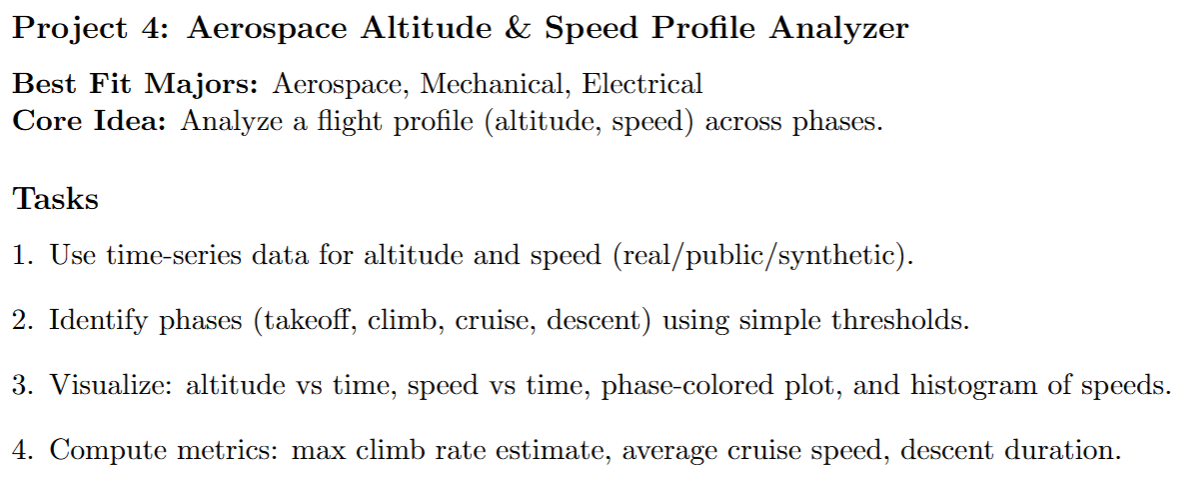

clc
clear

% load time-series data for altitude and speed
load('flight_data.csv') 
t = flight_data(:, 1); % define t from the data
alt = flight_data(:, 2); % define the altitude from the data
spd = flight_data(:, 3); % define the speed from the data

% identify flight phases using threshholds
vy = [0; (diff(alt))./(diff(t))]; % defines the vertical speed as the change in altitude over change in time

takeoff = alt < 100; % uses threshold to define takeoff phase
climb = vy > 2; % uses a threshold to define climb phase
cruise = abs(vy) < 5 & alt > 1000; % uses threshold to define cruise phase
descent = vy < -2; % uses threshold to define descent phase

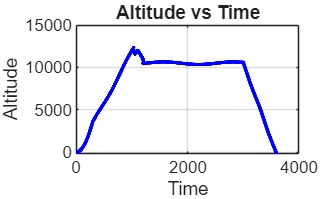

% creates an altitude vs time plot
plot(t, alt, 'b-', 'LineWidth', 2) % makes the line blue with a width of 2
title('Altitude vs Time') % titles the graph
ylabel('Altitude') % labels the y axis altitude
xlabel('Time') % labels the x axis time
grid on % turns on the grid lines

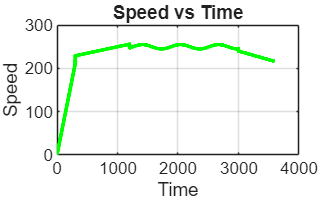

% creates a speed vs time plot
plot(t, spd, 'g-', 'LineWidth', 2) % makes the line green with a width of 2
title('Speed vs Time') % titles the graph
ylabel('Speed') % labels the y axis speed
xlabel('Time') % labels the x axis time
grid on % turns on the grid lines

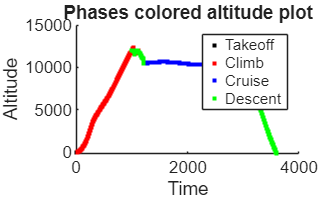

% phase colored altitude plot
figure
hold on % allows for multiple lines to be plotted on the same graph
plot(t(takeoff), alt(takeoff), 'k.', 'DisplayName', 'Takeoff') % plots the takeoff phase of altitude vs time
plot(t(climb), alt(climb), 'r.', 'DisplayName', 'Climb') % plots the climb phase of altitude vs time
plot(t(cruise), alt(cruise), 'b.', 'DisplayName', 'Cruise') % plots the cruise phase of altitude vs time
plot(t(descent), alt(descent), 'g.', 'DisplayName', 'Descent') % plots the descent phase of altitude vs time
title('Phases colored altitude plot') % titles the plot
xlabel('Time') % labels the x axis as time
ylabel('Altitude') % labels the y axis as altitude
legend % creates a legend to label on the plot what is representative of each phase
hold off % keeps any more plots from put on the same plot

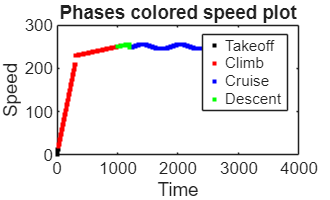

% phase colored speed plot
plot(t(takeoff), spd(takeoff), 'k.', 'DisplayName', 'Takeoff') % plots the takeoff phase for speed vs time
hold on % allows the following plots to be graphed on the same plot
plot(t(climb), spd(climb), 'r.', 'DisplayName', 'Climb') % plots the climb phase for speed vs time
plot(t(cruise), spd(cruise), 'b.', 'DisplayName', 'Cruise') % plots the cruise phase for speed vs time
plot(t(descent), spd(descent), 'g.', 'DisplayName', 'Descent') % plots the descent phase for speed vs time
title('Phases colored speed plot') % titles the plot
xlabel('Time') % labels the x axis time
ylabel('Speed') % labels the y axis speed
legend % turns on the legend to match the color to the phase it represents
hold off % keeps any more plots from going onto the same graph

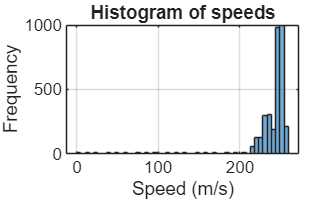

% histogram of speeds
histogram(spd,50) % creates a histogram, with 50 bins, that represents the frequency of the speeds of the aircraft
title('Histogram of speeds') % creates a title for the histogram
xlabel('Speed (m/s)') % labels the x-axis speed
ylabel('Frequency') % labels the y-axis frequency
grid on % turns on the grid lines

%max climb rate estimate
maxClimb = max(vy); % defines the max climb rate as the max of the vertical speed
fprintf('The maximum climb rate is: %g m/s', maxClimb) % displays the maximum climb rate

The maximum climb rate is: 60.8133 m/s

% average cruise speed
avgS = mean(cruise); % determines the average cruising speed
fprintf('The average cruising speed for the flight is %g m/s', avgS) % displays the average cruising speed

The average cruising speed for the flight is 0.499306 m/s

% descent duration
mean_t = mean(diff(t)); % average change in time
Tdescent = sum(descent) * mean_t; % finds the total time of the descent
fprintf('The duration of descent is %g', Tdescent) % displays the duration of descent

The duration of descent is 700